# Deconvolution Benchmark: Matlab (deconSingle)

addpath("WBDeconvolution/")

## Test Image

img = single(imread('ImagenPrueba.jpg'));
psf = single(imread('psf.jpg'));

output = DeconSingleView_fn(img,psf);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


f = @() DeconSingleView_fn(img,psf); 

timeit(f)

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back

ans = 0.6529

## Cell

img = single(imread("cells3d_convolved.tif"));
psf = single(imread("cells3d_psf.tif"));

output2 = DeconSingleView_fn(img,psf);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


f = @() DeconSingleView_fn(img,psf); 

timeit(f) % in seconds

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back

ans = 0.1754

## Cube of Spherical Beads

imgCube = tiffreadVolume('cubeConvolved.tif');
psfCube = tiffreadVolume('PSF.tif');

outputCube = DeconSingleView_fn(imgCube,psfCube);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!



f = @() DeconSingleView_fn(imgCube,psfCube); 
timeit(f) % in seconds

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back

ans = 0.9388

## _______________________________________________________________________

## C. Elegans embryo

function image_stack = load_image_stack(folder_path)
    % Listar todos los archivos en la carpeta y ordenar
    files = dir(fullfile(folder_path, '*.tif'));
    files = [files; dir(fullfile(folder_path, '*.png'))];
    files = [files; dir(fullfile(folder_path, '*.jpg'))];
    [~, index] = sort({files.name});
    files = files(index);
    
    % Leer la primera imagen para obtener las dimensiones
    first_image = imread(fullfile(folder_path, files(1).name));
    [height, width] = size(first_image);
    
    % Crear una matriz 3D vacía para almacenar las imágenes
    image_stack = zeros(height, width, length(files), 'single');
    
    % Leer el rango de valores para normalización
    max_val = double(max(first_image(:)));  % Valor máximo para normalización

    % Cargar cada imagen en la matriz 3D
    for i = 1:length(files)
        img = imread(fullfile(folder_path, files(i).name));
        % Convertir la imagen a single y normalizar
        image_stack(:, :, i) = single(img) / max_val;
    end
end


### Canal 1

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath1 = '/Users/yi/TFGNotebook/CElegans-CY3';
psfPath1 = '/Users/yi/TFGNotebook/PSF-CElegans-CY3';

% Cargar las imágenes en una matriz 3D
image_stack1 = load_image_stack(imagePath1);
psf_stack1 = load_image_stack(psfPath1);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack1 = image_stack1(1:356, 1:336, :);
psf_stack1 = psf_stack1(179:534,169:504, :);

% Obtener las dimensiones de image_stack
disp(size(image_stack1))

   356   336   104




% Obtener las dimensiones de psf_stack
disp(size(psf_stack1))

   356   336   104




outputChannel1 = DeconSingleView_fn(image_stack1,psf_stack1);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


f = @() DeconSingleView_fn(image_stack1,psf_stack1); 
timeit(f) % in seconds

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


ans = 9.9372

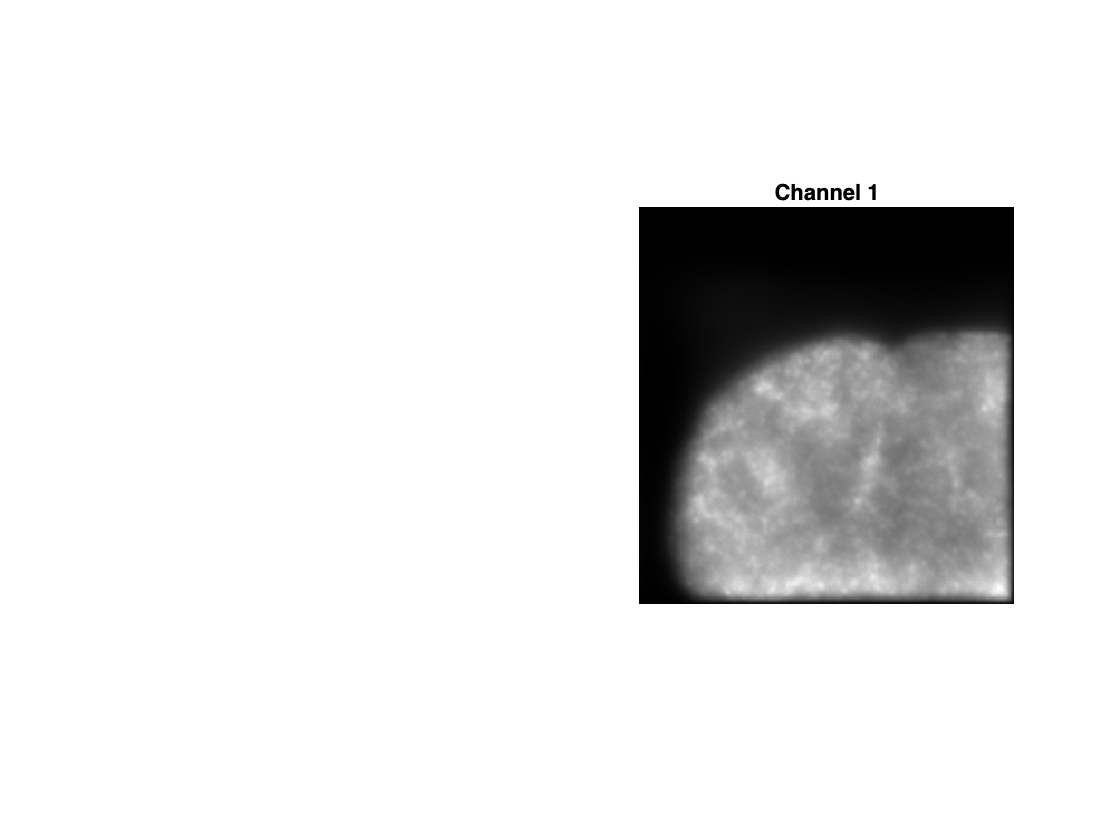

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(outputChannel1(:, :, 52),[]);

% Añadir título
title('Channel 1');

% Desactivar los ejes
axis off;